# שיעורי בית 1 התקנים אופטו-אלקטרוניים

c = 2.99e8;	                    % speed of light [m/s]
h = 6.63e-34;	                % Planck's constant [J s]
k = 1.38e-23;	                % Boltzmann's constant [J/K]
pi = 3.14;                      % eng pi
T_healthy = 273.15+36;          % healthy Temperature [K] 
T_sick= 273.15+39;              % sick temperature [K]
sigma = 5.673e-8;               % stefan boltzmann constant

## 1.1

Plank law:

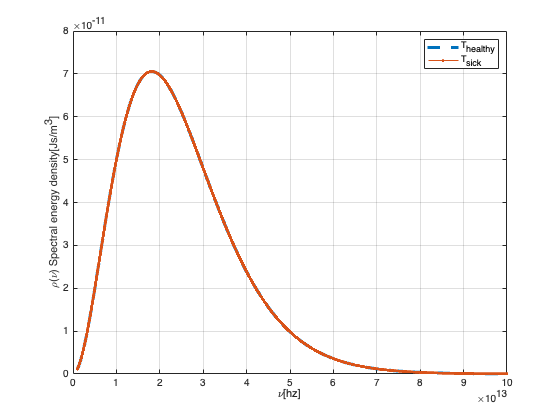

nu = 1e12:1e8:1e14;
rho_healthy = ((8.*pi.*nu.^3.*h)./(c^2)).*(1./(exp((h.*nu)./(k.*T_healthy))-1));
rho_sick = ((8.*pi.*nu.^3.*h)./(c^2)).*(1./(exp((h.*nu)./(k.*T_sick))-1));


plot(nu,rho_healthy,'--',LineWidth=3)
hold on
plot(nu,rho_healthy,'.-',LineWidth=1)
grid on;
legend('T_{healthy}','T_{sick}')
ylabel('\rho(\nu) Spectral energy density[Js/m^3]')
xlabel('\nu[hz]')

## 1.2

Stefan-Boltzman

P_per_area_healthy = sigma*T_healthy^4

P_per_area_healthy = 518.1909

P_per_area_sick = sigma*T_sick^4

P_per_area_sick = 538.5997

disp('In units of W*m^-2')

In units of W*m^-2


## 1.3

Wein

nu_max_healthy = 2.822*(k/h)*T_healthy

nu_max_healthy = 1.8159e+13

nu_max_sick = 2.822*(k/h)*T_sick

nu_max_sick = 1.8335e+13

disp('In hz units')

In hz units


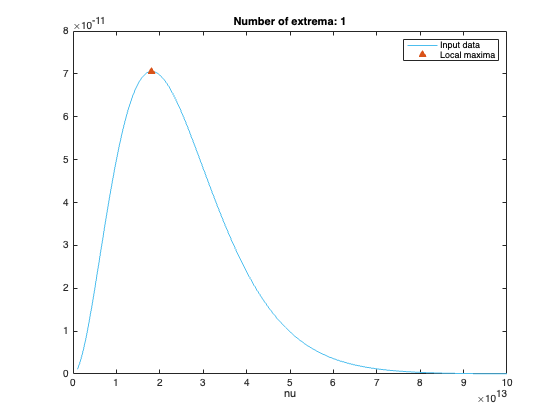

% Find local maxima
maxIndices_healthy = islocalmax(rho_healthy,"SamplePoints",nu);

% Display results
figure
plot(nu,rho_healthy,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(nu(maxIndices_healthy),rho_healthy(maxIndices_healthy),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices_healthy))
hold off
legend
xlabel("nu")

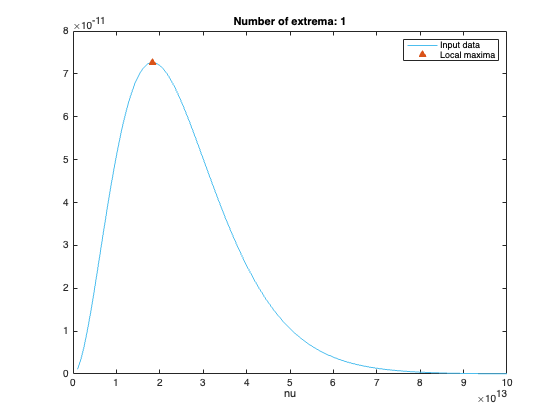

% Find local maxima
maxIndices_sick = islocalmax(rho_sick,"SamplePoints",nu);

% Display results
figure
plot(nu,rho_sick,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(nu(maxIndices_sick),rho_sick(maxIndices_sick),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices_sick))
hold off
legend
xlabel("nu")


res_array_Plank = [nu(maxIndices_healthy);nu(maxIndices_sick);abs(nu(maxIndices_healthy)-nu(maxIndices_sick))];
res_array_Wein = [nu_max_healthy;nu_max_sick;abs(nu_max_healthy-nu_max_sick)];
disp('Result table for nu_max')

Result table for nu_max


res_tab = table(res_array_Plank,res_array_Wein,'VariableNames',{'Plank','Wein'},'RowNames',{'Healthy','Sick','Delta'})

res_tab = 3×2 table
                 Plank          Wein   
               __________    __________

    Healthy    1.8155e+13    1.8159e+13
    Sick       1.8332e+13    1.8335e+13
    Delta       1.762e+11    1.7622e+11


## 1.4 

photoons number

E_photon_healthy = h*(nu(maxIndices_healthy));
E_photon_sick = h*(nu(maxIndices_sick));

number_of_photns_healthy = floor(P_per_area_healthy/E_photon_healthy)

number_of_photns_healthy = 4.3050e+22

number_of_photons_sick = floor(P_per_area_sick/E_photon_sick)

number_of_photons_sick = 4.4315e+22

disp('Units of #/s*A')

Units of #/s*A


## 2

syms pi c nu h k T rho(nu) B
eq_spec = rho(nu)==((8*pi*nu^3*h)/c^3)*(1)/(exp(h*nu/(k*T))-1)

$$eq\_spec = \rho \left(\nu \right)=\frac{8\,h\,\nu^{3}\,\pi }{c^{3}\,\left({\mathrm{e}}^{\frac{h\,\nu }{T\,k}}-1\right)}$$

D_rho = diff(eq_spec,nu)

$$D\_rho = \frac{\partial }{\partial \nu }\rho \left(\nu \right)=\frac{24\,h\,\nu^{2}\,\pi }{c^{3}\,\left({\mathrm{e}}^{\frac{h\,\nu }{T\,k}}-1\right)}-\frac{8\,h^{2}\,\nu^{3}\,\pi \,{\mathrm{e}}^{\frac{h\,\nu }{T\,k}}}{T\,c^{3}\,k\,{\left({\mathrm{e}}^{\frac{h\,\nu }{T\,k}}-1\right)}^{2}}$$

% Compute simplified symbolic expression
simplifiedExpr2 = simplify(D_rho,"Steps",6400)

$$simplifiedExpr2 = {\mathrm{e}}^{\frac{h\,\nu }{T\,k}}\neq 1\wedge c\neq 0\wedge 8\,h^{2}\,\nu^{3}\,\pi +T\,c^{3}\,k\,{\left({\mathrm{e}}^{\frac{h\,\nu }{T\,k}}-1\right)}^{2}\,\frac{\partial }{\partial \nu }\rho \left(\nu \right)=8\,h\,\nu^{2}\,\pi \,\left({\mathrm{e}}^{\frac{h\,\nu }{T\,k}}-1\right)\,\left(3\,T\,k-h\,\nu \right)$$

max_rho = D_rho == 0

$$max\_rho = \left(\frac{\partial }{\partial \nu }\rho \left(\nu \right)=\frac{24\,h\,\nu^{2}\,\pi }{c^{3}\,\left({\mathrm{e}}^{\frac{h\,\nu }{T\,k}}-1\right)}-\frac{8\,h^{2}\,\nu^{3}\,\pi \,{\mathrm{e}}^{\frac{h\,\nu }{T\,k}}}{T\,c^{3}\,k\,{\left({\mathrm{e}}^{\frac{h\,\nu }{T\,k}}-1\right)}^{2}}\right)=0$$


eq=(B*nu-3)*exp(B*nu)+3 == 0

$$eq = {\mathrm{e}}^{B\,\nu }\,\left(B\,\nu -3\right)+3=0$$

solve(eq,nu)

$$ans = \frac{W_{0}\left(-3\,{\mathrm{e}}^{-3}\right)+3}{B}$$

% Compute analytic solution of a symbolic equation
solution = solve(ans,B);
% Display symbolic solution returned by solve
displaySymSolution(solution);

 
solution =
 
Empty sym: 0-by-1
 
No solution exists.
